clear all;
close all;
clc;
%San Nic buoy correlation
%start time is Jun 12 2020 12:00:00
startTime = 20200612120000;
%end time is Jun 18 2020 17:00:00
endTime = 20200618170000;
%load glider data
gliderTable = readtable('metbuoy_26-04.csv');
%get waveglider time and wind vectors for appropriate times
[wgt wgWind10m ~] = gliderTime(gliderTable, startTime, endTime);
%upload san nic band frequency table
freqTable = readtable('San_Nic_Jun2020.txt');

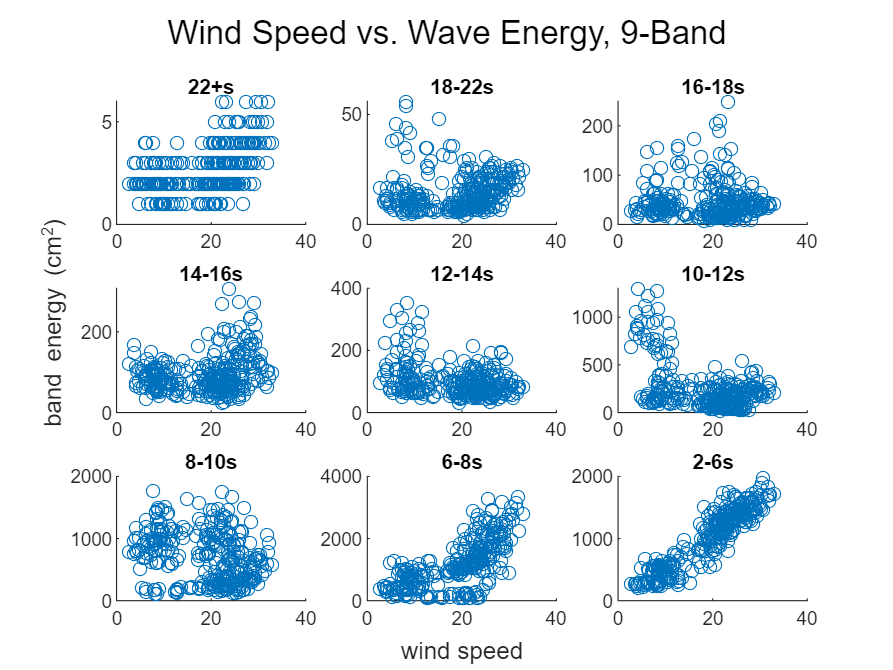

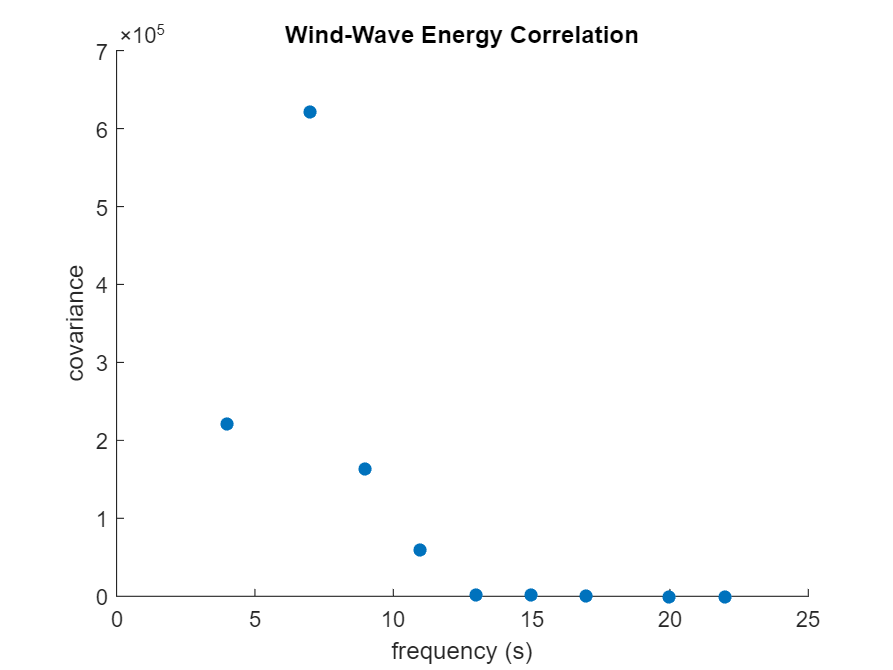

%correlation
windWaveCorr(freqTable, startTime, endTime, wgt, wgWind10m)